# tiledlayout截断坐标轴、共用colorbar、取消子图空隙

[MATLAB | 截断坐标轴、共用colorbar、取消子图空隙、tiledlayout函数全部秒杀 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247485561&idx=1&sn=96ae400c1b757215654cf0685b236dc2&chksm=cf6092d2f8171bc47b3988d2676dffbecf5086a6708978c33fa41edcf6e9c30cc7cce927832f&scene=178&cur_album_id=2736083636160020481#rd)

## PART.0 基础使用

使用tiledlayout函数创建布局，用nexttile在各个位置创建坐标区，然后在各个坐标区域绘制图像：

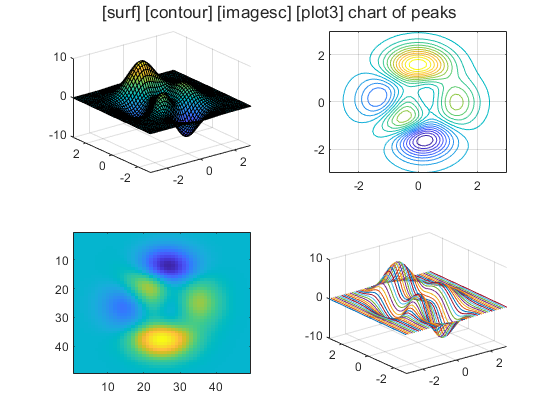

figure;tiledlayout(2,2);

[X,Y,Z]=peaks;

% 坐标区域块 1
nexttile
surf(X,Y,Z)

% 坐标区域块 2
nexttile
contour(X,Y,Z,20)
grid on

% 坐标区域块 3
nexttile
imagesc(Z)

% 坐标区域块 4
nexttile
plot3(X,Y,Z)
grid on

## 创建特殊大小的坐标区域：

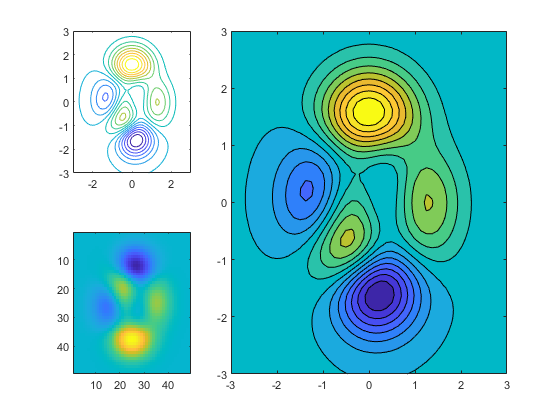


figure;tiledlayout(2,3);
[X,Y,Z]=peaks;

% 坐标区域块 1
nexttile
contour(X,Y,Z,15)

% 占据两行两列的坐标区域块
nexttile([2 2])
contourf(X,Y,Z,15)

% 坐标区域块 3
nexttile
imagesc(Z)

## 各个坐标区域大小和位置调整：

我们还是拿上面的代码举例，已经画好了图片依旧可以调整各个图块的位置和大小：

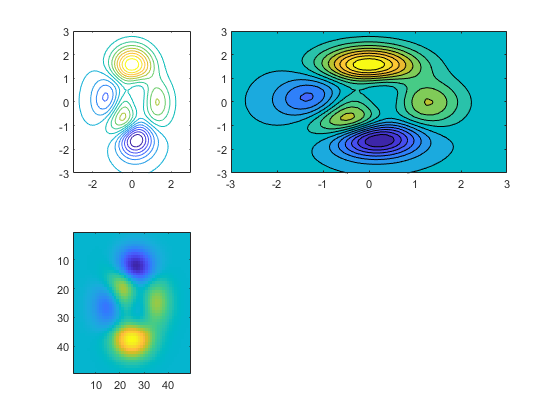


figure;tiledlayout(2,3);
[X,Y,Z]=peaks;

% 坐标区域块 1
nexttile
contour(X,Y,Z,15)

% 占据两行两列的坐标区域块
t22=nexttile([2 2]);
contourf(X,Y,Z,15);

% 坐标区域块 3
nexttile
imagesc(Z)

t22.Layout.Tile=2;         % 还是第二个图块
t22.Layout.TileSpan=[1 2]; % 占据大小变为1x2

###  PART.1 取消子图间隙及共用标题

可以设置TileSpacing来调整图块之间的空隙，可选参数如下(示例图可左右滑动)，从左到右依次是：

'loose'\'compact'\'tight'\'none'

可以设置Padding来调整图块和图窗边缘的空隙，可选参数有(示例图可左右滑动)，从左到右依次是：

'loose'\'compact'\'tight'

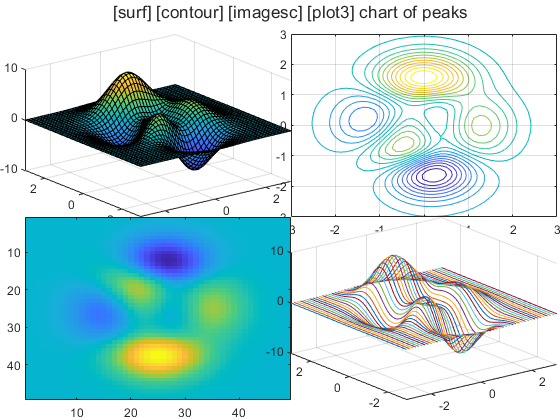

figure;tl=tiledlayout(2,2);
tl.TileSpacing='none';
tl.Padding='none';

[X,Y,Z]=peaks;

% 坐标区域块 1
nexttile
surf(X,Y,Z)

% 坐标区域块 2
nexttile
contour(X,Y,Z,20)
grid on

% 坐标区域块 3
nexttile
imagesc(Z)

% 坐标区域块 4
nexttile
plot3(X,Y,Z)
grid on

title(tl,'[surf] [contour] [imagesc] [plot3] chart of peaks')

###  PART.2 共用colorbar

就是正常画完colorbar后将其移动到：east位置图块。

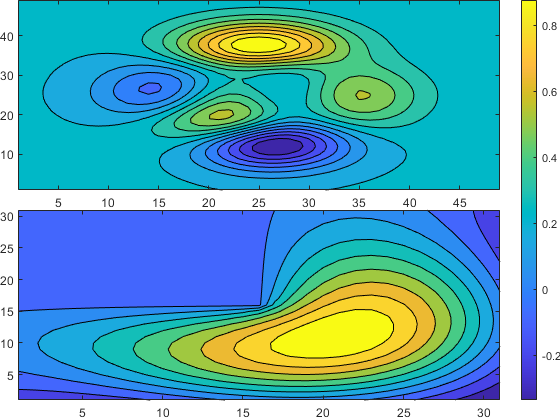

figure;tl=tiledlayout(2,1);
tl.TileSpacing='tight';
tl.Padding='tight';

Z1=peaks;
Z2=membrane;

% 坐标区域块 1
nexttile
contourf(Z1,15)

% 坐标区域块 2
nexttile
contourf(Z2,10)

cb=colorbar;
cb.Layout.Tile='east';

###  PART.3 多个colorbar

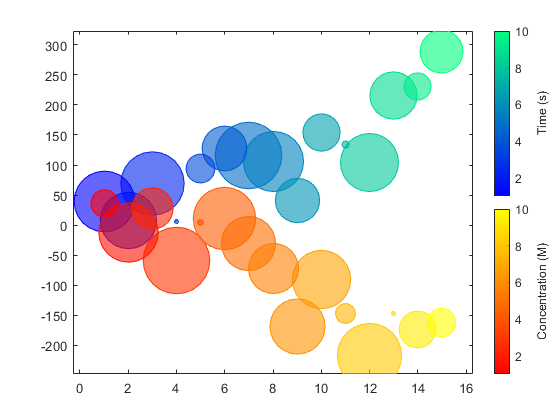


% 随便生成点数据
x=1:15;
n=70*randn(1,15)+50;
y1=n+x.^2; 
y2=n-linspace(1,225,15);
sz1=rand(1,15);
sz2=rand(1,15);
c=linspace(1,10,15);

% 创建冬天风格色带的气泡图
figure;
t=tiledlayout(1,1);
ax1=axes(t); 
bubblechart(ax1,x,y1,sz1,c)
colormap(ax1,'winter')

% 创建秋天风格色带的气泡图
ax2=axes(t);
bubblechart(ax2,x,y2,sz2,c)
colormap(ax2,'autumn')
ax2.Visible='off'; % 隐藏第二个坐标区域好让俩气泡图显示在一起

% 让两个气泡图的坐标范围相同完美融合
linkaxes(t.Children)

% 创建俩colorbar
cb1=colorbar(ax1);
cb1.Layout.Tile = 'east';
cb1.Label.String = 'Time (s)';

cb2=colorbar(ax2);
cb2.Layout.Tile='east';
cb2.Label.String='Concentration (M)';

 PART.4 截断坐标轴

实际原理就是画一个空白坐标区域打底，然后在画两个显示不同范围数据的坐标区域摆在一起。之后依旧要同步范围，这次同步的是y轴范围，就可以写：

linkaxes([ax1,ax2,... ...], 'y')

有一说一linkaxes这个函数也挺好用的。

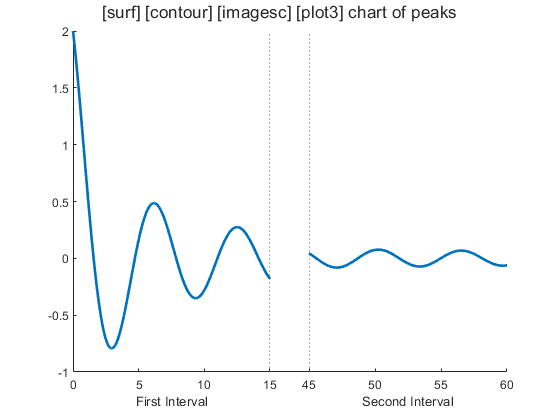


% 绘制最底下的坐标区域
figure;t=tiledlayout(1,2,'TileSpacing','compact');
bgAx=axes(t,'XTick',[],'YTick',[],'Box','off');
bgAx.Layout.TileSpan = [1 2];

% 生成数据
x=0:0.1:60;
y=4.*cos(x)./(x+2);

% 绘制[0,15]范围坐标区域
ax1=axes(t);
plot(ax1,x,y,'LineWidth',2)
xline(ax1,15,':');
ax1.Box='off';
xlim(ax1,[0 15])
xlabel(ax1,'First Interval')

% 绘制[45 60]范围坐标区域
ax2=axes(t);
ax2.Layout.Tile=2;
plot(ax2,x,y,'LineWidth',2)
xline(ax2,45,':');
ax2.YAxis.Visible='off';
ax2.Box='off';
xlim(ax2,[45 60])
xlabel(ax2,'Second Interval')

% 同步y轴坐标范围
linkaxes([ax1 ax2], 'y')